# Detecting Malaria with CNN

## How simple can it be?

Dataset: [https://ceb.nlm.nih.gov/repositories/malaria-datasets/](https://ceb.nlm.nih.gov/repositories/malaria-datasets/) 

clr
filepath = strcat(pwd, "\data_edited");
imds = imageDatastore(filepath, 'IncludeSubfolders',true,'LabelSource','foldernames');

## Data exploration

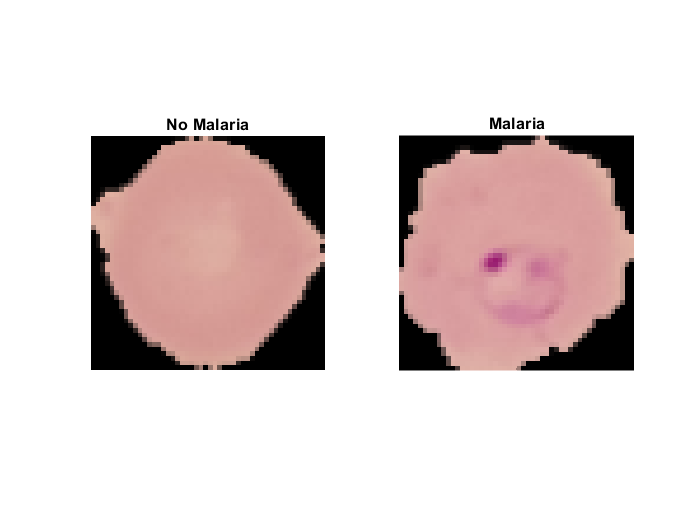

labelCount = countEachLabel(imds);
subplot(1, 2, 1)
imshow(imds.Files{1})
title("No Malaria")


subplot(1, 2, 2)
imshow(imds.Files{13780})
title("Malaria")

disp(labelCount)

    Label    Count
    _____    _____
      0      13779
      1      13779


imSize = size(imread(imds.Files{1}));
numberOfLabels = length(unique(imds.Labels));

## Train Test split

trainingSize = 0.75;
rng(1)
[trainData, testData] = splitEachLabel(imds, trainingSize, 'randomize');

## Using the deep network designer to design my deep network

deepNetworkDesigner

Load network via mat file.

load("network_layers.mat")

options = trainingOptions('sgdm', 'MaxEpochs', 5, 'InitialLearnRate', 0.001);
CNN = trainNetwork(trainData, layers, options);

Training on single CPU.
Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:03 |       46.88% |       6.1580 |          0.0010 |


% save('malariaCNN.mat', 'CNN')

CNN = load("malariaCNN.mat");
CNN = CNN.CNN;

## Result

close
[yTest, scores] = classify(CNN, testData);
tTest = testData.Labels;
accuracy = sum(yTest == tTest)/(numel(tTest));
disp(accuracy)

## plot result

close all
labels = ["No Malaria", "Malaria"];
index = randperm(6890, 12);

for ii = 1:numel(index)
    I = readimage(testData, index(ii));
    pred = (yTest(index(ii)));
    label = tTest(index(ii));
    if label == pred
        color = 'g';
    else
        color = 'r';
    end
    
    subplot(3, 4, ii)
    imshow(I)
    title(sprintf("pred: %s\n(%s)", labels{pred}, labels{label}), "Color", color)
end
text(100, 20,sprintf("accuracy = %0.2f%%", accuracy*100));
figure("Color","w");
plotconfusion(tTest, yTest);
title(sprintf("accuracy = %0.2f%%", accuracy*100));

clf
histogram(scores(tTest == "1" & yTest == "0", 1), 10);
title("Confidence frequency of False Negatives")
xlabel("Confidence")
ylabel("Frequency")
editScores = scores;
threshold = 0.75;
underThresh = scores(:, 1) < threshold & scores(:, 1) > 0.50;
editScores(underThresh, 1) = editScores(underThresh, 1) - 0.50;
[M, I] = max(editScores, [], 2);
yTest2 = I-1;
yTest2 = categorical(yTest2);
accuracy2 = sum(yTest2 == tTest)/(numel(tTest))
figure("Color","w");
plotconfusion(tTest, yTest2);
figure;
ax1 = subplot(2, 1, 1);
hist2 = histogram(editScores(tTest == "1" & yTest2 == "0", 1), "BinWidth",0.05);
title("New")

ax2 = subplot(2, 1, 2);
hist = histogram(scores(tTest == "1" & yTest == "0", 1), "BinWidth",0.05);
axis([0 1 0 35])
title("Old")
xlabel("Confidence")
linkaxes([ax1,ax2],'xy')